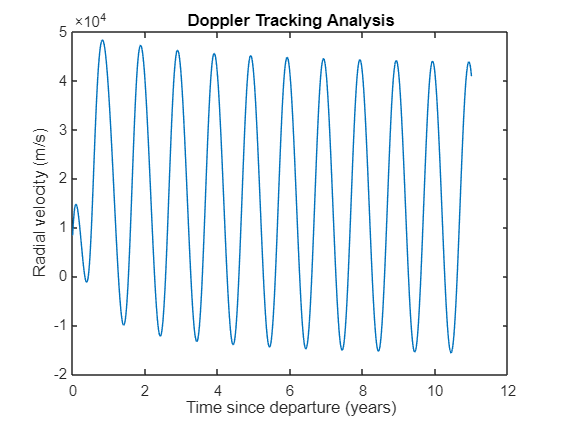

% Constants
mu_sun = 1.32712440018e20; % Sun's gravitational parameter (m^3/s^2)
c = 299792458; % Speed of light (m/s)
AU = 1.496e11; % Astronomical unit (m)
deg2rad = pi/180;
rad2deg = 180/pi;

% Given Orbital Elements (converted to SI units)
a = -8.67833125301e11; % Semi-major axis (m) [Negative for hyperbolic]
e = 1.174823; % Eccentricity
i = 2.742 * deg2rad; % Inclination (rad)
RAAN = 73.100 * deg2rad; % Right Ascension of Ascending Node (rad)
omega = 178.272 * deg2rad; % Argument of Periapsis (rad)
theta_dep = 0.466 * deg2rad; % True anomaly at departure (rad)
h = 6.617357042738070e15; % Specific angular momentum (m^2/s)

% Departure and Arrival Dates (MJD2000)
departure_mjd = 12205.50;
arrival_mjd = 16222.50;
time = linspace(0, (arrival_mjd - departure_mjd)*86400, 1000); % Time since departure (s)

function [earth_pos, earth_vel] = getEarthPosition(mjd2000)
    % Approximate Earth's position using Keplerian orbit (Simplified)
    AU = 149597870700;
    T = 365.256363 * 86400; % Orbital period (s)
    t = mjd2000 * 86400; % Time since MJD2000 (s)
    M = 2*pi * t / T; % Mean anomaly
    E = M; % Initial guess for eccentric anomaly (approx for circular orbit)
    earth_pos = [cos(E), sin(E), 0] * AU; % Position (m)
    earth_vel = [-sin(E), cos(E), 0] * (2*pi*AU / T); % Velocity (m/s)
end

function [r_sc, v_sc] = spacecraftState(t, a, e, mu, h, i, RAAN, omega, theta_dep)
    % Solve hyperbolic Kepler's equation for time t
    n = sqrt(mu / (-a)^3); % Mean motion (rad/s)
    M = n * t; % Mean anomaly
    H = solveKeplerHyperbolic(M, e, 1e-6); % Hyperbolic anomaly
    
    % True anomaly
    theta = 2 * atan(sqrt((e + 1)/(e - 1)) * tanh(H / 2));
    
    % Position and velocity in perifocal frame
    r_pf = (h^2 / mu) / (1 + e*cos(theta)) * [cos(theta); sin(theta); 0];
    v_pf = (mu / h) * [-sin(theta); e + cos(theta); 0];
    
    % Rotation matrix to heliocentric frame
    R = rotationMatrix(i, RAAN, omega);
    r_sc = R * r_pf;
    v_sc = R * v_pf;
end

function H = solveKeplerHyperbolic(M, e, tol)
    % Newton-Raphson to solve M = e*sinh(H) - H
    H = M; % Initial guess
    for iter = 1:100
        f = e * sinh(H) - H - M;
        df = e * cosh(H) - 1;
        dH = -f / df;
        H = H + dH;
        if abs(dH) < tol
            break;
        end
    end
end

function R = rotationMatrix(i, RAAN, omega)
    % 3-1-3 Euler rotation
    Rz_RAAN = [cos(RAAN), -sin(RAAN), 0; sin(RAAN), cos(RAAN), 0; 0, 0, 1];
    Rx_i = [1, 0, 0; 0, cos(i), -sin(i); 0, sin(i), cos(i)];
    Rz_omega = [cos(omega), -sin(omega), 0; sin(omega), cos(omega), 0; 0, 0, 1];
    R = Rz_RAAN * Rx_i * Rz_omega;
end

radial_velocity = zeros(size(time));
frequency_shift = zeros(size(time));
for k = 1:length(time)
    t = time(k);
    mjd = departure_mjd + t/86400;
    [earth_pos, earth_vel] = getEarthPosition(mjd);
    [r_sc, v_sc] = spacecraftState(t, a, e, mu_sun, h, i, RAAN, omega, theta_dep);
    
    % Relative velocity
    v_rel = v_sc' - earth_vel;
    r_vec = r_sc' - earth_pos;
    unit_r = r_vec / norm(r_vec);
    radial_velocity(k) = dot(v_rel, unit_r);
    
    % Doppler shift (assuming nominal frequency f0)
    f0 = 8.4e9; % Example: 2.4 GHz
    frequency_shift(k) = f0 * (1 + radial_velocity(k)/c);
end

% Plot Radial Velocity
figure;
plot(time/(86400*365.25), radial_velocity);
xlabel('Time since departure (years)');
ylabel('Radial velocity (m/s)');
title('Doppler Tracking Analysis');

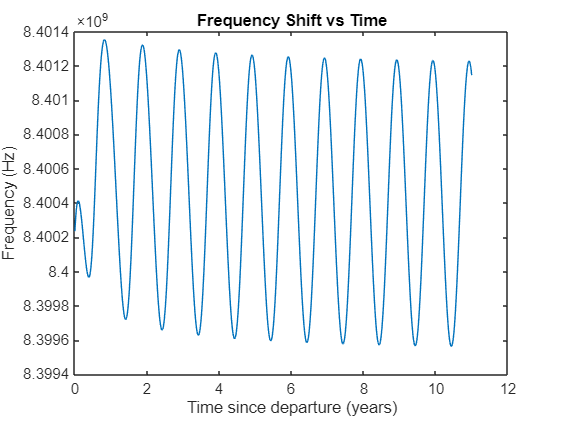


% Plot Frequency Shift
figure;
plot(time/(86400*365.25), frequency_shift);
xlabel('Time since departure (years)');
ylabel('Frequency (Hz)');
title('Frequency Shift vs Time');

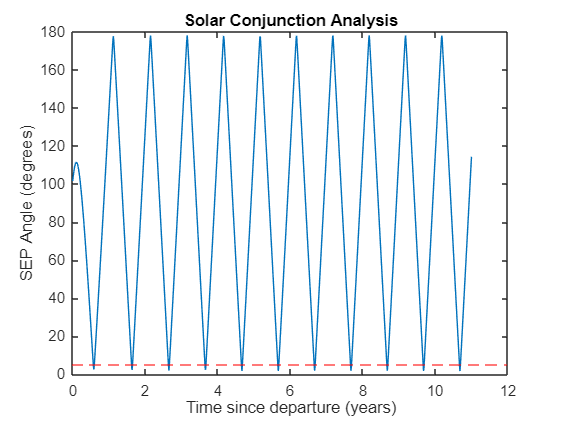


sep_angle = zeros(size(time));
critical_angle = 5; % Degrees
for k = 1:length(time)
    mjd = departure_mjd + time(k)/86400;
    earth_pos = getEarthPosition(mjd);
    [r_sc, ~] = spacecraftState(time(k), a, e, mu_sun, h, i, RAAN, omega, theta_dep);
    
    % SEP angle
    sun_earth = earth_pos;
    sun_sc = r_sc';
    sep_angle(k) = acosd(dot(sun_earth, sun_sc)/(norm(sun_earth)*norm(sun_sc)));
end

% Plot SEP Angle
figure;
plot(time/(86400*365.25), sep_angle);
yline(critical_angle, 'r--');
xlabel('Time since departure (years)');
ylabel('SEP Angle (degrees)');
title('Solar Conjunction Analysis');

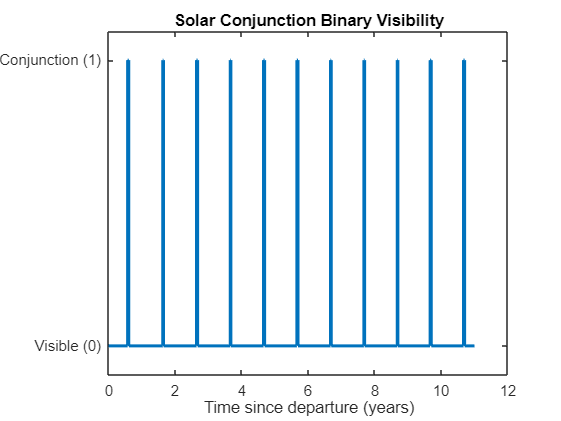


% Convert SEP angles to binary (1 = SEP < 5°)
binary_sep = sep_angle < critical_angle;

% Plot binary SEP visibility
figure;
stairs(time/(86400*365.25), binary_sep, 'LineWidth', 2);
ylim([-0.1 1.1]);
yticks([0 1]);
yticklabels({'Visible (0)', 'Conjunction (1)'});
xlabel('Time since departure (years)');
title('Solar Conjunction Binary Visibility');

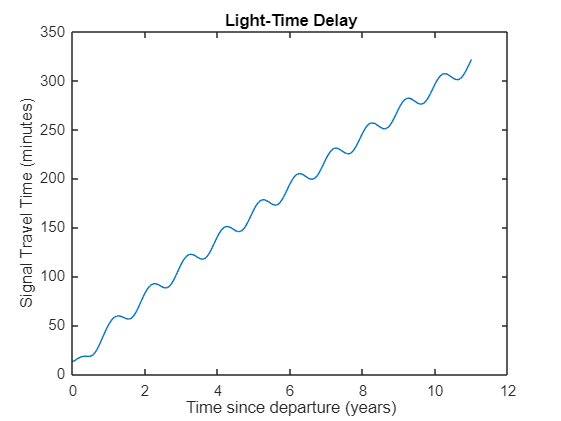


light_time = zeros(size(time));
for k = 1:length(time)
    mjd = departure_mjd + time(k)/86400;
    earth_pos = getEarthPosition(mjd);
    [r_sc, ~] = spacecraftState(time(k), a, e, mu_sun, h, i, RAAN, omega, theta_dep);
    distance = norm(r_sc' - earth_pos);
    light_time(k) = distance / c;
end

% Plot Light-Time Delay
figure;
plot(time/(86400*365.25), light_time/60);
xlabel('Time since departure (years)');
ylabel('Signal Travel Time (minutes)');
title('Light-Time Delay');

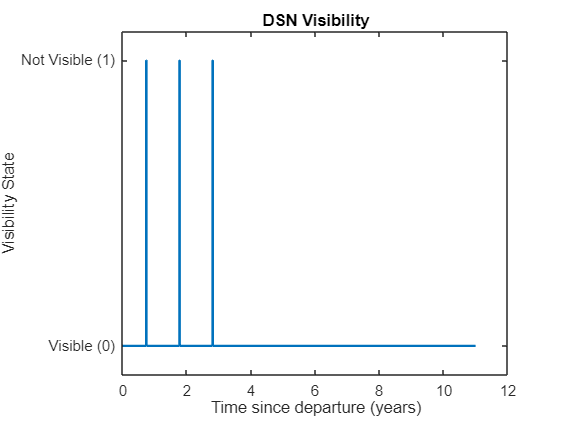


% DSN Visibility Analysis with 10° Elevation Rule
visibility = zeros(size(time)); % 1 = Not Visible, 0 = Visible
dsn_stations = [-116.8900, 35.4267;  % Goldstone (longitude, latitude)
                -4.2481,   40.4322;   % Madrid
                148.9817, -35.4014];  % Canberra

for k = 1:length(time)
    % Get Earth and spacecraft positions
    mjd = departure_mjd + time(k)/86400;
    [earth_pos, ~] = getEarthPosition(mjd);
    [r_sc, ~] = spacecraftState(time(k), a, e, mu_sun, h, i, RAAN, omega, theta_dep);
    
    % Vector from Earth to spacecraft (heliocentric -> geocentric)
    r_earth_sc = r_sc' - earth_pos(:); % Ensure column vectors
    
    % Convert to RA/Dec (equatorial coordinates)
    [ra, dec] = cart2radec(r_earth_sc);
    
    % Check visibility at all DSN stations
    visible = false;
    for s = 1:size(dsn_stations, 1)
        % Station parameters
        lon = dsn_stations(s, 1); % Longitude (deg)
        lat = dsn_stations(s, 2); % Latitude (deg)
        
        % Calculate Local Sidereal Time (LST)
        lst = mjd2lst(mjd, lon); % In degrees
        
        % Local Hour Angle
        lha = lst - ra; % Degrees
        
        % Elevation calculation (NASA DSN requires >10°)
        elev = asind(sind(dec)*sind(lat) + cosd(dec)*cosd(lat)*cosd(lha));
        
        % Visibility check (10° elevation rule)
        if elev > 10 % Reference: NASA DSN Interface Document (810-5)
            visible = true;
            break; % Visible to at least one station
        end
    end
    
    % Invert logic for binary plot: 1 = Not Visible, 0 = Visible
    visibility(k) = ~visible; 
end

% Plot Binary DSN Visibility
figure;
stairs(time/(86400*365.25), visibility, 'LineWidth', 1.5);
ylim([-0.1 1.1]);
yticks([0 1]);
yticklabels({'Visible (0)', 'Not Visible (1)'});
xlabel('Time since departure (years)');
ylabel('Visibility State');
title('DSN Visibility');


function [ra, dec] = cart2radec(r)
    dec = asind(r(3)/norm(r));
    ra = atan2d(r(2), r(1));
    ra = mod(ra, 360);
end

function lst = mjd2lst(mjd, lon)
    % Convert MJD2000 to LST
    jd = mjd + 2451545.0; % Convert to Julian Date
    T = (jd - 2451545.0)/36525;
    gmst = 280.46061837 + 360.98564736629*(jd - 2451545.0) + 0.000387933*T^2;
    lst = mod(gmst + lon, 360)/15; % Convert to hours
    lst = lst * 15; % Convert to degrees
end
